# Sinais em tempo discreto

## Boas práticas

## Abrindo arquivos

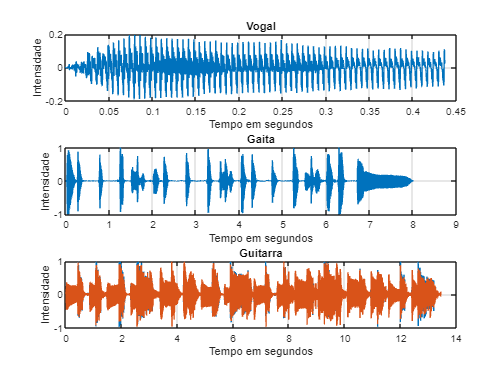

% audioread Read audio files
%     [Y, FS] = audioread(FILENAME) reads an audio file specified by the
%     character vector or string scalar FILENAME, returning the sampled data
%     in Y and the sample rate FS, in Hertz.

[ya, fs1] = audioread("a.wav");
[yg, fs2] = audioread("Gaita_Blues.wav");
[yl, fs3] = audioread("Guitarra_limpa.wav");


%%%%% eixo tempo %%%%%

tempo_a = 0 : 1/fs1 : (length(ya)-1)*(1/fs1);
tempo_g = 0 : 1/fs2 : (length(yg)-1)*(1/fs2);
tempo_l = 0 : 1/fs3 : (length(yl)-1)*(1/fs3);


%%%%% visualizando %%%%%

figure(1)
subplot(3, 1, 1); 
plot(tempo_a, ya);
title('Vogal');
xlabel('Tempo em segundos');
ylabel('Intensidade'); grid;

subplot(3, 1, 2); 
plot(tempo_g, yg);
title('Gaita');
xlabel('Tempo em segundos');
ylabel('Intensidade'); grid;

subplot(3, 1, 3); 
plot(tempo_l, yl);
title('Guitarra');
xlabel('Tempo em segundos');
ylabel('Intensidade'); grid;

## Fourier dos arquivos

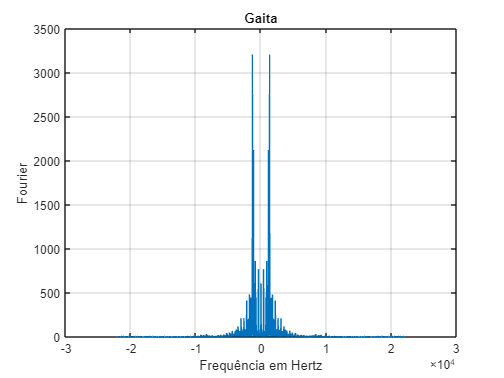

Ya = fft(ya);
Yg = fft(yg);
Yl = fft(yl);

 % fft Discrete Fourier transform. → Fast Fourier Transform
 %    fft(X) is the discrete Fourier transform (DFT) of vector X.  For
 %    matrices, the fft operation is applied to each column. For N-D
 %    arrays, the fft operation operates on the first non-singleton
 %    dimension.

 %%%%% eixo frequência %%%%%

 freq_g = linspace(-fs2/2, fs2/2, length(yg));

 %%%%% visualizando %%%%%

 figure(2)
 subplot(1, 1, 1);
 plot(freq_g, fftshift(abs(Yg)));
 title('Gaita');
 xlabel('Frequência em Hertz');
 ylabel('Fourier'); grid;

## Filtrando os dados

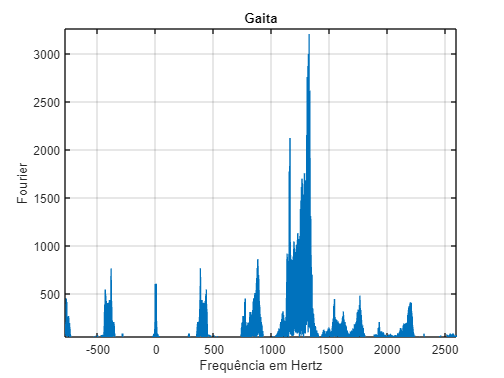

N = 2;

%%%%% filtra os pontos do arquivo %%%%%

ygf = yg(1 : N : end);

%%%%% fourier %%%%%

Ygf = fft(ygf);

%%%%% eixo frequência %%%%%

freq_gf = linspace(-fs2/(2*N), fs2/(2*N), length(ygf));

%%%%% visualizando %%%%%

figure(3)
subplot(1, 1, 1);

plot(freq_g, fftshift(abs(Ygf)));
title('Gaita Filtrada'); xlabel('frequência em Hz'); ylabel('Fourier'); grid;

